# 1-D Random Walk

1-D random walk with a single molecule at a time. This uses integer unit step sizes along with equal sized time steps for each step. Multiple runs of the single molecule will be performed in order to calculate averages and statistics.

clear;
close all;
tic
N = 1000;   %number of steps
Sims = 5000; %number of simulations

x = zeros(Sims,N+1);  %locations

Left_Weight = 0.5;

for i = 1:Sims
    LeftCounter = 0;
    RightCounter = 0;
    for j = 1:N
        R = rand;
        if R < Left_Weight  %left step
            x(i,j+1) = x(i,j)-1;
            LeftCounter = LeftCounter+1;
        else   %right step
            x(i,j+1) = x(i,j)+1;
            RightCounter = RightCounter+1;
        end
    end
    Counter(i) = abs(RightCounter-LeftCounter);    %distance from 0
    Counter_Avg(i) = mean(Counter);
    d(i) = abs(x(i,end));    %average position after N steps
    d_real(i) = mean(d);   %real average position
end

d_theor = sqrt(2*N/pi)  %calculated avg position

d_theor = 25.2313

toc

Elapsed time is 37.912564 seconds.


figure();
plot(1:Sims,d_real);   hold on;
yline(d_theor,'.','Expected');

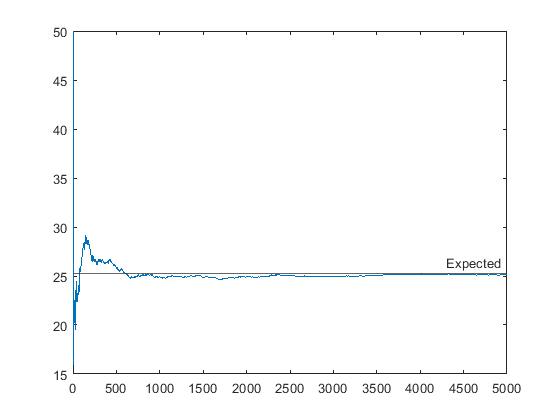

xlim([0 Sims]);

This should produce similar results but it will be done in a different way. Now all simulations will be run at the same time, hopefully working in a faster and mor eeffective method.

clear;
close all;
tic
N = 1000;   %number of steps taken
Sims = 5000;    %number of simulations (random walkers) done
Left_Weight = 0.5;  %probability of left vs right step

x = zeros(Sims,N+1);
D = zeros(1,N+1);

for i = 1:N
    R = rand([Sims,1]);
    x(R<=Left_Weight,i+1) = x(R<=Left_Weight,i)-1;  %left movement
    x(R>Left_Weight,i+1) = x(R>Left_Weight,i)+1;    %right movement
    
    D(i+1) = mean(abs(x(:,i+1)));
end
D_Th = [0,sqrt(2.*[1:N]./pi)];
D_Th1 = [0, sqrt([1:N])];
toc

Elapsed time is 0.443446 seconds.


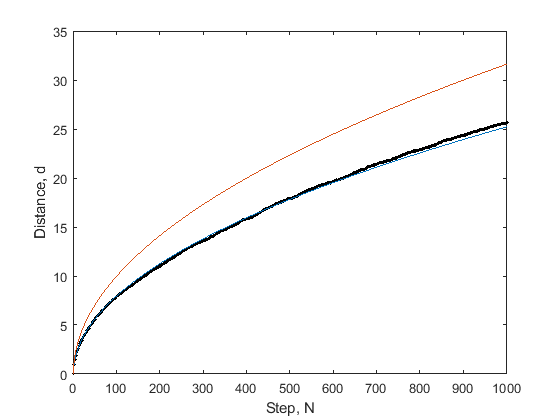

figure();
scatter(1:N+1,D,3,'k','filled');    hold on;
plot(1:N+1,D_Th);   box on;
plot(1:N+1,D_Th1);
xlim([0 N+1]);
xlabel('Step, N');  ylabel('Distance, d');